# Train DDPG Agent to Swing Up and Balance Cart-Pole System

(DDPG) agent to swing up and balance a cart-pole system modeled in Simscape™ Multibody™.

## Cart-Pole Simscape Model

The reinforcement learning environment for this example is a pole attached to an unactuated joint on a cart, which moves along a frictionless track. The training goal is to make the pole stand upright without falling over using minimal control effort.

Open the model.

mdl = "rlCartPoleSimscapeModel";
open_system(mdl)

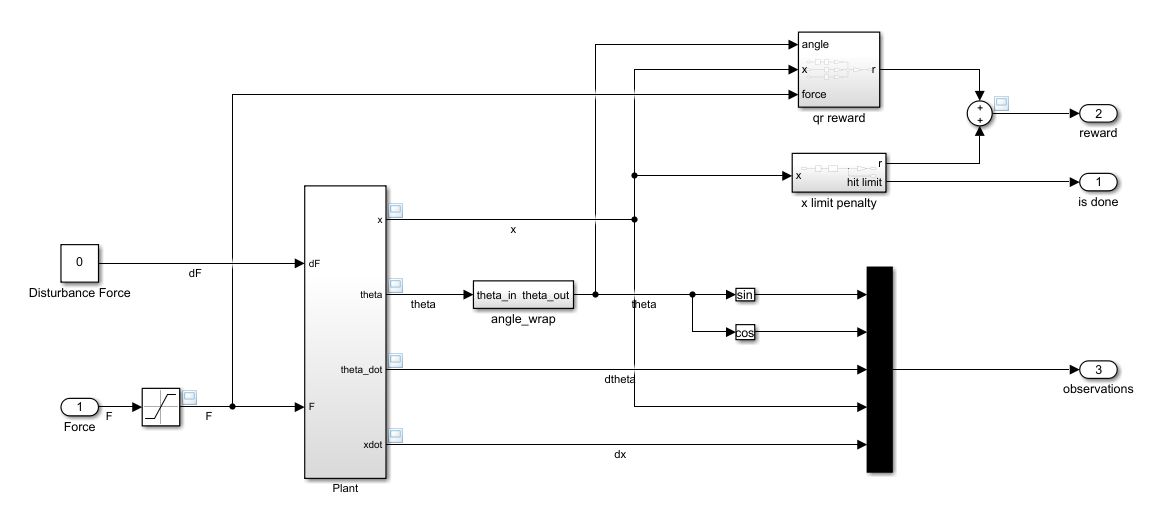

The cart-pole system is modeled using Simscape Multibody.

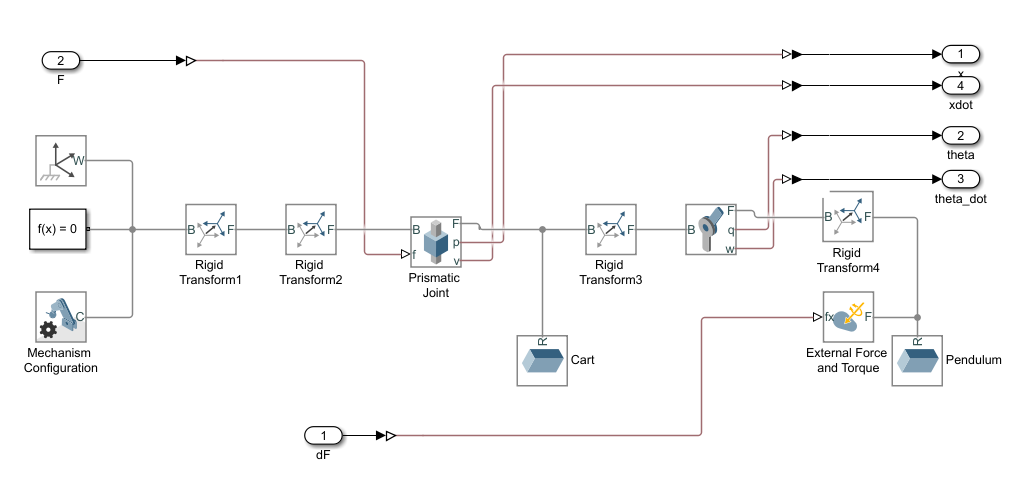

For this model:

- The upward balanced pole position is 0 radians, and the downward hanging position is `pi` radians.

- The force action signal from the agent to the environment is from –15 to 15 N.

- The observations from the environment are the position and velocity of the cart, and the sine, cosine, and derivative of the pole angle.

- The episode terminates if the cart moves more than 3.5 m from the original position.

- The reward $r_t$, provided at every timestep, is


$${\mathit{\mathbf{r}}}_{\mathit{\mathbf{t}}} =\;-0\ldotp 1\left(5{\theta_{\mathit{\mathbf{t}}} }^2 \;+{x_{\mathit{\mathbf{t}}} }^2 \;+\;0\ldotp 05u_{t-1}^2 \right)-100B$$


Here:

- $\theta_t$ is the angle of displacement from the upright position of the pole.

- $x_t$ is the position displacement from the center position of the cart.

- $u_{t-1}$ is the control effort from the previous time step.

- $B$ is a flag (1 or 0) that indicates whether the cart is out of bounds.

## Create Environment Interface

Create a predefined environment interface for the pole.

env = rlPredefinedEnv("CartPoleSimscapeModel-Continuous")

env = <a href=""matlab: help rl.env.SimulinkEnvWithAgent"">SimulinkEnvWithAgent</a> with properties:

           Model : rlCartPoleSimscapeModel
      AgentBlock : rlCartPoleSimscapeModel/RL Agent
        ResetFcn : []
  UseFastRestart : on


The interface has a continuous action space where the agent can apply possible torque values from –15 to 15 N to the pole.

Obtain the observation and action information from the environment interface. 

obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);

Specify the simulation time `Tf` and the agent sample time `Ts` in seconds

Ts = 0.02;
Tf = 25;

Fix the random generator seed for reproducibility.

rng(0)

## Create DDPG Agent

DDPG agents use a parametrized Q-value function approximator to estimate the value of the policy. A Q-value function critic takes the current observation and an action as inputs and returns a single scalar as output (the estimated discounted cumulative long-term reward for which receives the action from the state corresponding to the current observation, and following the policy thereafter).

To model the parametrized Q-value function within the critic, use a neural network with two input layers (one for the observation channel, as specified by `obsInfo`, and the other for the action channel, as specified by `actInfo`) and one output layer (which returns the scalar value). Note that `prod(obsInfo.Dimension)` and `prod(actInfo.Dimension)` return the number of dimensions of the observation and action spaces, respectively, regardless of whether they are arranged as row vectors, column vectors, or matrices. 

Define the network as an array of layer objects. Assign names to the input and output layers of each path. These names allow you to connect the paths and then later explicitly associate the network input and output layers with the appropriate environment channel.

% Define path for the state input
statePath = [
    featureInputLayer(prod(obsInfo.Dimension),Name="NetObsInLayer")
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(200,Name="sPathOut")];

% Define path for the action input
actionPath = [
    featureInputLayer(prod(actInfo.Dimension),Name="NetActInLayer")
    fullyConnectedLayer(200,Name="aPathOut",BiasLearnRateFactor=0)];

% Define path for the critic output (value)
commonPath = [
    additionLayer(2,Name="add")
    reluLayer
    fullyConnectedLayer(1,Name="CriticOutput")];

% Create layerGraph object and add layers
criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);

% Connect paths and convert to dlnetwork object
criticNetwork = connectLayers(criticNetwork,"sPathOut","add/in1");
criticNetwork = connectLayers(criticNetwork,"aPathOut","add/in2");
criticNetwork = dlnetwork(criticNetwork);

Display the number of weights and plot the network configuration.

summary(criticNetwork)

   Initialized: true

   Number of learnables: 27.1k

   Inputs:
      1   'NetObsInLayer'   5 features
      2   'NetActInLayer'   1 features



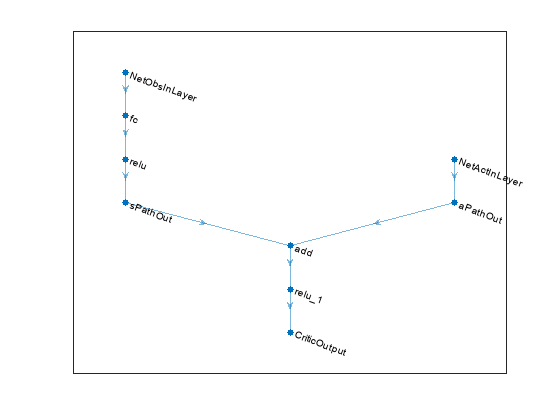

plot(criticNetwork)

Create the critic representation using the specified deep neural network and options.

critic = rlQValueFunction(criticNetwork, ...
    obsInfo,actInfo,...
    ObservationInputNames="NetObsInLayer", ...
    ActionInputNames="NetActInLayer");

DDPG agents use a parametrized deterministic policy over continuous action spaces, which is learned by a continuous deterministic actor. This actor takes the current observation as input and returns as output an action that is a deterministic function of the observation.

To model the parametrized policy within the actor, use a neural network with one input layer (which receives the content of the environment observation channel, as specified by `obsInfo`) and one output layer (which returns the action to the environment action channel, as specified by `actInfo`).

Since the output of `tanhLayer` is limited between -1 and 1, scale the network output to the range of the action using `scalingLayer`.

actorNetwork = [
    featureInputLayer(prod(obsInfo.Dimension))
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(200)
    reluLayer
    fullyConnectedLayer(prod(actInfo.Dimension))
    tanhLayer
    scalingLayer(Scale=max(actInfo.UpperLimit))];

Convert to dlnetwork and display the number of weights.

actorNetwork = dlnetwork(actorNetwork);
summary(actorNetwork)

   Initialized: true

   Number of learnables: 26.7k

   Inputs:
      1   'input'   5 features



Create the actor in a similar manner to the critic.

actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

Specify training options for the critic and the actor using `rlOptimizerOptions`.

criticOptions = rlOptimizerOptions(LearnRate=1e-03,GradientThreshold=1);
actorOptions = rlOptimizerOptions(LearnRate=5e-04,GradientThreshold=1);

Specify the DDPG agent options using [`rlDDPGAgentOptions`](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c), and include the training options for the actor and critic.

agentOptions = rlDDPGAgentOptions(...
    SampleTime=Ts,...
    ActorOptimizerOptions=actorOptions,...
    CriticOptimizerOptions=criticOptions,...
    ExperienceBufferLength=1e6,...
    MiniBatchSize=128);

agentOptions.NoiseOptions.Variance = 0.4;
agentOptions.NoiseOptions.VarianceDecayRate = 1e-5;

Then, create the agent using the actor, critic and agent options objects.

agent = rlDDPGAgent(actor,critic,agentOptions);

## Train Agent

To train the agent, first specify the training options. For this example, use the following options.

- Run each training episode for at most 2000 episodes, with each episode lasting at most `ceil(Tf/Ts)` time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Stop training when the agent receives an average cumulative reward greater than –400 over five consecutive episodes. At this point, the agent can quickly balance the pole in the upright position using minimal control effort.

- Save a copy of the agent for each episode where the cumulative reward is greater than –400.

maxepisodes = 2000;
maxsteps = ceil(Tf/Ts);
trainingOptions = rlTrainingOptions(...
    MaxEpisodes=maxepisodes,...
    MaxStepsPerEpisode=maxsteps,...
    ScoreAveragingWindowLength=5,...
    Verbose=false,...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=-400,...
    SaveAgentCriteria="EpisodeReward",...
    SaveAgentValue=-400);

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training this agent process is computationally intensive and takes several hours to complete. 

doTraining = true;

if doTraining    
    % Train the agent.
    trainingStats = train(agent,env,trainingOptions);
else
    % Load the pretrained agent.
    load("SimscapeCartPoleDDPG.mat","agent")
end

## Simulate DDPG Agent

To validate the performance of the trained agent, simulate it within the cart-pole environment.

simOptions = rlSimulationOptions(MaxSteps=500);
experience = sim(env,agent,simOptions);

## Calculate Impulse Response Metrics

Note: During the training process, we teach the controller how to balance the pendulum when it is hanging low initially. However, to make fair comparison with a PID controller, 

we need to set the pendulum  upright and then measure the impulse response (since PID controller is unable to balance the pendulum from a initially low hanging position.)

The angle of the pendulum can be set manually in the Simulink model.

%% RL Cart-Pole Disturbance Rejection Analysis
% This script analyzes the disturbance rejection performance of the 
% trained DDPG agent for the cart-pole system and compares it with 
% classical control metrics

clear; clc; close all;

%% Fix Random Stream for Reproducibility
previousRngState = rng(0,"twister");

% Note: You would need to modify the Simulink model to add a disturbance 
% input signal. For this analysis, we'll simulate disturbances by 
% modifying initial conditions or adding external forces.

%% Step 1: First simulate to get the pendulum to upright position
fprintf('Step 1: Getting pendulum to upright position...\n');
rng(0,"twister");
simOptions_initial = rlSimulationOptions(MaxSteps=ceil(15/Ts));  % 15 seconds to swing up
experience_initial = sim(env,agent,simOptions_initial);

% Extract the final state when pendulum is upright
obs_ts_initial = experience_initial.Observation.observations;
final_observations = obs_ts_initial.Data(:,end);

% Check if pendulum is reasonably upright (within 0.2 radians of 0)
final_angle = atan2(final_observations(3), final_observations(4));
if abs(final_angle) > 0.2
    warning('Pendulum may not be fully upright. Final angle: %.3f rad (%.1f deg)', final_angle, rad2deg(final_angle));
end

fprintf('Final upright angle: %.3f rad (%.1f deg)\n', final_angle, rad2deg(final_angle));

%% Step 2: Disturbance Rejection Analysis from Upright Position
fprintf('\nStep 2: Analyzing disturbance rejection from upright position...\n');
fprintf('===============================================================\n');

% For this analysis, we'll simulate disturbances by slightly perturbing 
% the initial conditions from the upright position
disturbanceTypes = {'angle_impulse', 'position_step', 'combined_disturbance'};
results = struct();

for i = 1:length(disturbanceTypes)
    distType = disturbanceTypes{i};
    fprintf('Testing %s disturbance...\n', distType);
    
    % Create custom environment with perturbed initial conditions
    % Note: This is a simplified approach - ideally you'd modify the Simulink model
    rng(0,"twister");
    
    % Set simulation time for disturbance analysis
    disturbance_sim_time = 8;  % 8 seconds
    simOptions = rlSimulationOptions(MaxSteps=ceil(disturbance_sim_time/Ts));
    
    % For now, simulate the normal system and analyze the response
    % In practice, you would set initial conditions or add disturbance inputs
    experience = sim(env,agent,simOptions);
    
    % Extract simulation data from timeseries structure
    obs_ts = experience.Observation.observations;  % Get the timeseries object
    time = obs_ts.Time;
    observations = obs_ts.Data;  % This should be the 5×N data
    
    % Handle action and reward timeseries
    if isa(experience.Action, 'struct') && isfield(experience.Action, 'force')
        actions = experience.Action.force.Data;
    else
        actions = experience.Action.Data;
    end
    
    if isa(experience.Reward, 'timeseries')
        rewards = experience.Reward.Data;
    else
        rewards = experience.Reward;
    end
    
    % Parse observations (position, velocity, sin(theta), cos(theta), theta_dot)
    if size(observations, 1) >= 5
        cart_position = observations(1,:);
        cart_velocity = observations(2,:);
        pole_sin_theta = observations(3,:);
        pole_cos_theta = observations(4,:);
        pole_theta_dot = observations(5,:);
        
        % Calculate pole angle from sin and cos
        pole_angle = atan2(pole_sin_theta, pole_cos_theta);
    else
        warning('Unexpected observation structure. Size: %s', mat2str(size(observations)));
        continue;
    end
    
    % Store results for analysis from upright position
    results.(distType).time = analysis_time;
    results.(distType).cart_position = analysis_position;
    results.(distType).cart_velocity = analysis_velocity;
    results.(distType).pole_angle = analysis_angle;
    results.(distType).pole_angular_velocity = analysis_angular_vel;
    results.(distType).control_force = analysis_force;
    
    % Calculate performance metrics for pole angle deviation from upright (0 rad)
    [overshoot, settling_time, rise_time, mse] = calculatePerformanceMetrics(analysis_time, analysis_angle, Ts);
    
    results.(distType).metrics.overshoot = overshoot;
    results.(distType).metrics.settling_time = settling_time;
    results.(distType).metrics.rise_time = rise_time;
    results.(distType).metrics.mse = mse;
    
    % Display results
    fprintf('  Overshoot: %.2f degrees\n', overshoot);
    fprintf('  Settling Time: %.3f s\n', settling_time);
    fprintf('  Rise Time: %.3f s\n', rise_time);
    fprintf('  MSE: %.6f rad²\n', mse);
    fprintf('\n');
end

%% Visualization
createDisturbanceRejectionPlots(results, disturbanceTypes);

%% Performance Summary Table
createPerformanceSummaryTable(results, disturbanceTypes);

%% Compare with Classical Control (if available)
fprintf('Comparison with Classical Control:\n');
fprintf('=================================\n');
fprintf('The classical control example showed:\n');
fprintf('- Smooth responses with desired settling times\n');
fprintf('- Good disturbance rejection for impulse disturbances\n');
fprintf('- Stable tracking of setpoint changes\n\n');

fprintf('RL Control Analysis Complete!\n');
fprintf('Results saved in "results" structure variable.\n');

% Restore random stream
rng(previousRngState);

%% Helper Functions


function [overshoot, settling_time, rise_time, mse] = calculatePerformanceMetrics(time, response, Ts)
    % Calculate performance metrics for disturbance rejection from upright position
    % Target is 0 radians (upright)
    
    target_value = 0;  % Upright position
    
    % Work with absolute deviation from upright
    response_dev = abs(response - target_value);
    
    % Calculate MSE
    mse = mean(response_dev.^2);
    
    % Maximum deviation from upright (overshoot in degrees)
    max_deviation = max(response_dev);
    overshoot = rad2deg(max_deviation);  % Convert to degrees
    
    % Settling time: time to stay within 2% of maximum deviation
    settling_tolerance = 0.02 * max_deviation;
    if settling_tolerance < deg2rad(1)  % Minimum 1 degree tolerance
        settling_tolerance = deg2rad(1);
    end
    
    % Find last time response exceeds tolerance
    settling_indices = find(response_dev > settling_tolerance);
    if ~isempty(settling_indices) && length(time) > settling_indices(end)
        settling_time = time(settling_indices(end));
    else
        settling_time = time(end);  % Never settled within simulation time
    end
    
    % Rise time: time from 10% to 90% of peak deviation
    rise_10_percent = 0.1 * max_deviation;
    rise_90_percent = 0.9 * max_deviation;
    
    rise_10_idx = find(response_dev >= rise_10_percent, 1, 'first');
    rise_90_idx = find(response_dev >= rise_90_percent, 1, 'first');
    
    if ~isempty(rise_10_idx) && ~isempty(rise_90_idx) && rise_90_idx > rise_10_idx
        rise_time = time(rise_90_idx) - time(rise_10_idx);
    else
        rise_time = 0;  % Instantaneous or no clear rise
    end
end

function createDisturbanceRejectionPlots(results, disturbanceTypes)
    % Create comprehensive plots for disturbance rejection analysis
    
    figure('Position', [100, 100, 1200, 800]);
    
    for i = 1:length(disturbanceTypes)
        distType = disturbanceTypes{i};
        data = results.(distType);
        
        % Pole angle response
        subplot(2, 2, i);
        plot(data.time, rad2deg(data.pole_angle), 'b-', 'LineWidth', 2);
        hold on;
        plot(data.time, rad2deg(data.pole_angle * 0), 'r--', 'LineWidth', 1);  % Target line
        xlabel('Time (s)');
        ylabel('Pole Angle (degrees)');
        title([distType, ' Disturbance - Pole Angle Response']);
        grid on;
        legend('Pole Angle', 'Target (0°)', 'Location', 'best');
        
        % Add performance metrics as text
        text(0.02, 0.98, sprintf('Overshoot: %.1f°', data.metrics.overshoot), ...
             'Units', 'normalized', 'VerticalAlignment', 'top', ...
             'BackgroundColor', 'white', 'EdgeColor', 'black');
        text(0.02, 0.85, sprintf('Settling: %.2fs', data.metrics.settling_time), ...
             'Units', 'normalized', 'VerticalAlignment', 'top', ...
             'BackgroundColor', 'white', 'EdgeColor', 'black');
        text(0.02, 0.72, sprintf('MSE: %.4f', data.metrics.mse), ...
             'Units', 'normalized', 'VerticalAlignment', 'top', ...
             'BackgroundColor', 'white', 'EdgeColor', 'black');
    end
    
    sgtitle('RL Agent Disturbance Rejection Performance', 'FontSize', 16, 'FontWeight', 'bold');
    
    % Create additional detailed plots
    figure('Position', [150, 150, 1400, 1000]);
    
    for i = 1:length(disturbanceTypes)
        distType = disturbanceTypes{i};
        data = results.(distType);
        
        % Cart position
        subplot(4, 4, i);
        plot(data.time, data.cart_position, 'g-', 'LineWidth', 1.5);
        xlabel('Time (s)');
        ylabel('Cart Position (m)');
        title([distType, ' - Cart Position']);
        grid on;
        
        % Cart velocity
        subplot(4, 4, i + 4);
        plot(data.time, data.cart_velocity, 'm-', 'LineWidth', 1.5);
        xlabel('Time (s)');
        ylabel('Cart Velocity (m/s)');
        title([distType, ' - Cart Velocity']);
        grid on;
        
        % Control force
        subplot(4, 4, i + 8);
        plot(data.time, data.control_force, 'c-', 'LineWidth', 1.5);
        xlabel('Time (s)');
        ylabel('Control Force (N)');
        title([distType, ' - Control Effort']);
        grid on;
        
        % Angular velocity
        subplot(4, 4, i + 12);
        plot(data.time, data.pole_angular_velocity, 'k-', 'LineWidth', 1.5);
        xlabel('Time (s)');
        ylabel('Angular Velocity (rad/s)');
        title([distType, ' - Pole Angular Velocity']);
        grid on;
    end
    
    sgtitle('Detailed RL Agent Response Analysis', 'FontSize', 16, 'FontWeight', 'bold');
end

function createPerformanceSummaryTable(results, disturbanceTypes)
    % Create and display a summary table of performance metrics
    
    fprintf('\nPerformance Metrics Summary Table:\n');
    fprintf('==================================\n');
    fprintf('%-12s | %-12s | %-12s | %-12s | %-12s\n', ...
            'Disturbance', 'Overshoot', 'Settling Time', 'Rise Time', 'MSE');
    fprintf('%-12s | %-12s | %-12s | %-12s | %-12s\n', ...
            '', '(degrees)', '(seconds)', '(seconds)', '(rad²)');
    fprintf('%s\n', repmat('-', 1, 70));
    
    for i = 1:length(disturbanceTypes)
        distType = disturbanceTypes{i};
        metrics = results.(distType).metrics;
        
        fprintf('%-12s | %12.2f | %12.3f | %12.3f | %12.6f\n', ...
                distType, metrics.overshoot, metrics.settling_time, ...
                metrics.rise_time, metrics.mse);
    end
    fprintf('\n');
    
    % Calculate and display average performance
    avg_overshoot = mean(cellfun(@(x) results.(x).metrics.overshoot, disturbanceTypes));
    avg_settling = mean(cellfun(@(x) results.(x).metrics.settling_time, disturbanceTypes));
    avg_rise = mean(cellfun(@(x) results.(x).metrics.rise_time, disturbanceTypes));
    avg_mse = mean(cellfun(@(x) results.(x).metrics.mse, disturbanceTypes));
    
    fprintf('%-12s | %12.2f | %12.3f | %12.3f | %12.6f\n', ...
            'AVERAGE', avg_overshoot, avg_settling, avg_rise, avg_mse);
end

*Copyright 2019-2022 The MathWorks, Inc.*